% Author: Christopher Bourjaili
% Module 2
% Project 7
% Title: Robot Motion in One Dimension
%
% Summary of Code:
% - Simulates robot motion along one dimension over time.
% - Applies velocity limits and acceleration constraints.
% - Updates position and velocity using time-stepped logic.
% - Detects stopping and reversing motion events.
% - Creates position vs time and velocity vs time plots.
% - Demonstrates how limits affect robot movement.
%
% What I Learned:
% This project demonstrated how MATLAB can model robotic motion using
% kinematics, loops, and numerical simulation methods. I learned that
% acceleration constraints control how quickly a robot can speed up or
% slow down, while velocity limits prevent unsafe motion. I also practiced
% detecting important motion events such as stopping and reversing.

clc
clear
close all

dt = 0.1;                 
t_max = 20;              

t = 0:dt:t_max;
n = length(t);

v_max = 3;               
a_max = 0.5;             

position = zeros(1,n);
velocity = zeros(1,n);
accel = zeros(1,n);

stop_detected = false;
reverse_detected = false;


for i = 2:n

    if t(i) <= 6
        accel(i) = a_max;          
        
    elseif t(i) <= 12
        accel(i) = -a_max;         
        
    else
        accel(i) = -a_max;         
    end

    velocity(i) = velocity(i-1) + accel(i)*dt;

    if velocity(i) > v_max
        velocity(i) = v_max;
    elseif velocity(i) < -v_max
        velocity(i) = -v_max;
    end

    position(i) = position(i-1) + velocity(i)*dt;

    if velocity(i) == 0 && ~stop_detected && t(i) > 0
        fprintf('Robot stopped at %.2f seconds\n', t(i));
        stop_detected = true;
    end

    if velocity(i) < 0 && ~reverse_detected
        fprintf('Robot reversed direction at %.2f seconds\n', t(i));
        reverse_detected = true;
    end
    
end

Robot reversed direction at 12.00 seconds


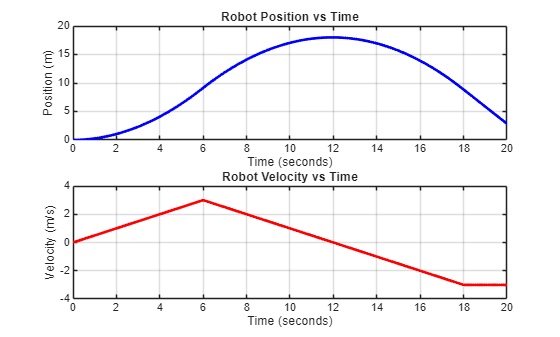


figure

subplot(2,1,1)
plot(t, position,'b','LineWidth',2)
grid on
xlabel('Time (seconds)')
ylabel('Position (m)')
title('Robot Position vs Time')

subplot(2,1,2)
plot(t, velocity,'r','LineWidth',2)
grid on
xlabel('Time (seconds)')
ylabel('Velocity (m/s)')
title('Robot Velocity vs Time')


disp('Motion Analysis:')

Motion Analysis:


disp('1. Robot accelerates forward until speed limit is reached.')

1. Robot accelerates forward until speed limit is reached.


disp('2. Robot slows down under negative acceleration.')

2. Robot slows down under negative acceleration.


disp('3. Robot stops, then reverses direction.')

3. Robot stops, then reverses direction.


disp('4. Velocity and acceleration constraints create smooth motion.')

4. Velocity and acceleration constraints create smooth motion.
